Задание основных параметров системных объектов

% Загрузка коэффициентов фильтров
Data = load("nummat.mat");
nummat = Data.nummat;
% Параметры и системные объекты чтения файла
SamplesPerFrame = 100;
fileInfo = audioinfo('nagradyi-ritm-animatsii-zvuka-39535.wav');
fileReader = dsp.AudioFileReader('nagradyi-ritm-animatsii-zvuka-39535.wav');
fileReader.SamplesPerFrame = SamplesPerFrame;
% Системный объект воспроизведения
deviceWriter = audioDeviceWriter('SampleRate', fileInfo.SampleRate);
% Системный объект КИХ-фильтра с измененными коэффициентами
Md = dsp.FIRFilter('Structure',"Direct form symmetric",'NumeratorSource','Input port');
mu = 0.008; % шаг LMS фильтра
ha = dsp.LMSFilter('Method',"LMS",'StepSize',mu,'Length',32);

пепепепеп

Основной цикл обработки:

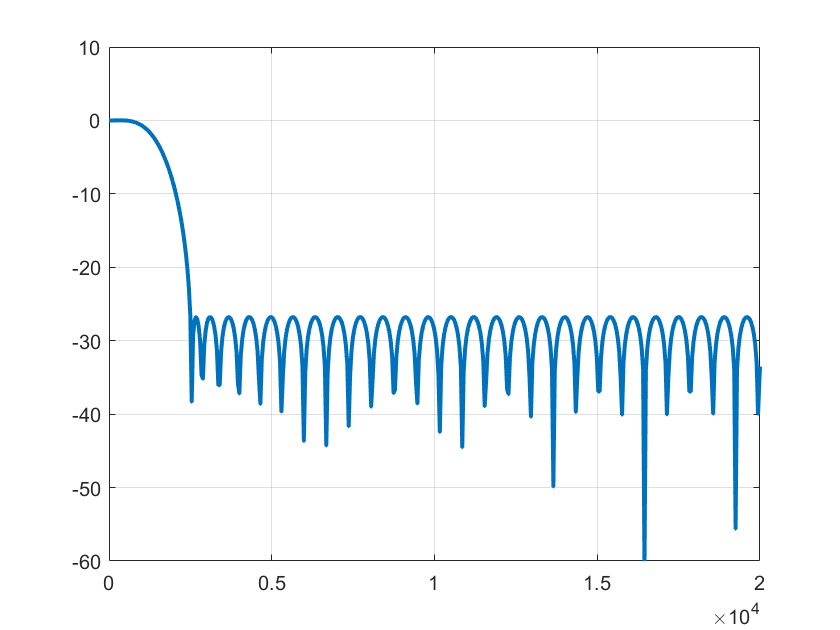

Num = nummat(2,:);
[h,f] = freqz(Num,1,[],fileInfo.SampleRate);
plot(f,10*log10(abs(h)),'LineWidth',2); grid on; xlim([0 20e3]); ylim([-60 10]);


while ~isDone(fileReader)
    audioData = fileReader();
    audioData = ha(audioData,Num);
    deviceWriter(audioData);
end

Error using dsp.LMSFilter/parenReference
Not enough input arguments. Expected 2 (in addition to System object), got 1.


reset(fileReader);
reset(deviceWriter);

конец

clear, clc;
close all;
mu = 0.008; % шаг LMS фильтра
ha = dsp.LMSFilter;
%[y2,err2] = filter(ha,s,n);
%figure, plot(t,[x;y2;err2])
title('Адаптивная фильтрация')
xlim([0 0.2])
grid on
legend('x','y','err')
close all